Companion software for "Volker Ziemann, *Hands-on Accelerator physics using MATLAB, CRCPress, 2019*" (https://www.crcpress.com/9781138589940)

# Longitudinal bunch rotation (Section 5.5)

Volker Ziemann, 211207, CC-BY-SA-4.0

**Important:** requires the elliptic package from [https://github.com/moiseevigor/elliptic](https://github.com/moiseevigor/elliptic) located in a subdirectory below the present one (for the fast evaluation of elliptic functions).

In this simulation we slowly (adiabatically) reduce the RF voltage, which lengthens the bunch while at the same time reduces the momentum spread. We then suddenly turn on the RF again, which causes the bunch to rotate in phase space such that after a quarter of  synchrotron period the bunch is short.

## Matched initial distribution

In the first step we define the parameters of the system and the initial particle distribution that is randomly distributed in a short range of phases and momenta. Then we move the coordinates of each particle forward in time by $100$ synchrotron periods, which causes the initial distribution to smear out into a matched longitudinal distribution, which we use as starting distribution.

clear;
addpath ./elliptic
Omegas=0.25; Ts=2*pi/Omegas; % synchrotron frequency
dt=100*Ts;   % or 100*Ts   % <--- set time here
N=1000;      % number of particles
x0=[0.0,0.0]; dx=[0.5,0.1];  % center and spread of initialdistribution
x=zeros(N,2); x1=x;
for k=1:N   % loop over particles
  x(k,:)=x0+(rand(1,2)-0.5).*dx; 
  x1(k,:)=pendulumtracker(x(k,:),Omegas,dt); % initial distribution
end

We now save the initial distribution as` x` and also calculate the rms bunch length `initial_rms`, which is given in degree RF phase.

x=x1;
initial_rms=std(x1(:,1))*180/pi;

## Slowly reducing the RF voltage

Now we reduce the RF-voltage, which also reduces $\Omega_s$ to ten percent of its original value. This is visible by the shrinking separatrix. At the same time the particle distribution increases in the phase-direction and shrinks in the momentum-direction. At the end we are left with a longer beam that has a smaller momentum spread.

nstep=100; 
nstep2=90;
for nb=1:nstep2-1
  hold off; 
  Omegas=0.25*(nstep-nb)/nstep; Ts=2*pi/Omegas; dt=100*Ts;
  phi=-pi:0.01:pi; separatrix=2*Omegas*cos(0.5*phi);
  plot(phi,separatrix,'k',phi,-separatrix,'k');
  hold on
  parfor k=1:N   % loop over particles, or use "for"
    x1(k,:)=pendulumtracker(x1(k,:),Omegas,dt);
  end
  plot(x1(:,1),x1(:,2),'r.')
  axis([-pi,pi,-0.67,0.67]);
  set(gca,'xtick',[-pi,-pi/2,0,pi/2,pi],'fontsize',14, ...
     'xticklabels',{'-\pi','-\pi/2','0','\pi/2','\pi'})
  text(-2.8,-0.57,['After ',num2str(nb,'%4d'),' steps'],'fontsize',16) 
  pause(0.001)
end

Again we calculate the rms length of the bunch` final_rms` and superimpose the initial distribution of particles as a cloud of green dots.

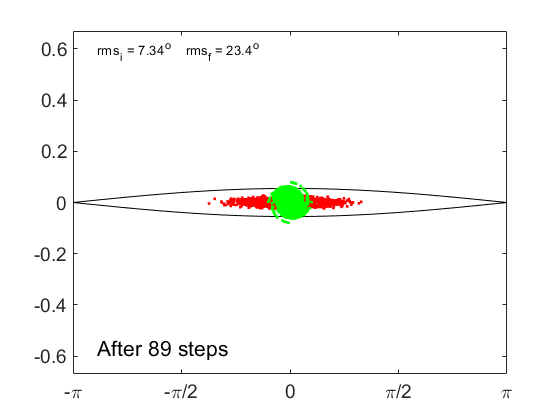

final_rms=std(x1(:,1))*180/pi;
plot(x(:,1),x(:,2),'g.')
text(-2.8,0.59,['rms_i = ',num2str(initial_rms,3),'^o    rms_f = ',num2str(final_rms,3),'^o'])

## Suddenly turn on RF again and wait for a quarter synchrotron oscillation

In the final step we turn on the RF voltage to its original value, which sets $\Omega_s$ back to the initial value of 0.25 and plot the separatrix before following the particles for a quarter of a synchrotron period $T_s/4$. Finally we plot the distribution and annotate the axes.  Note also the rms bunch length displayed in the legend.

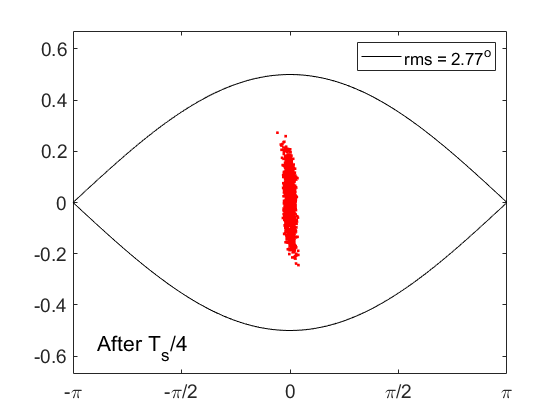

figure  
Omegas=0.25; Ts=2*pi/Omegas; 
phi=-pi:0.01:pi; separatrix=2*Omegas*cos(0.5*phi);
plot(phi,separatrix,'k',phi,-separatrix,'k');
hold on
parfor k=1:N   % loop over particles, or use "for"
  x1(k,:)=pendulumtracker(x1(k,:),Omegas,Ts/4);
end
plot(x1(:,1),x1(:,2),'r.')
axis([-pi,pi,-0.67,0.67]);
set(gca,'xtick',[-pi,-pi/2,0,pi/2,pi],'fontsize',14, ...
     'xticklabels',{'-\pi','-\pi/2','0','\pi/2','\pi'})
text(-2.8,-0.57,'After T_s/4','fontsize',16) 
rot_rms=std(x1(:,1))*180/pi;
legend(['rms = ',num2str(rot_rms,3),'^o'])

In the upper part of the following plot we show the projection of the initial distribution, corresponding to the cloud of green dots shown on a earlier plot, and display its rms width in the legend. Then we repeat the same thing with the final distribution after the bunch rotation and display the ratio of the rms values as the `compression`.

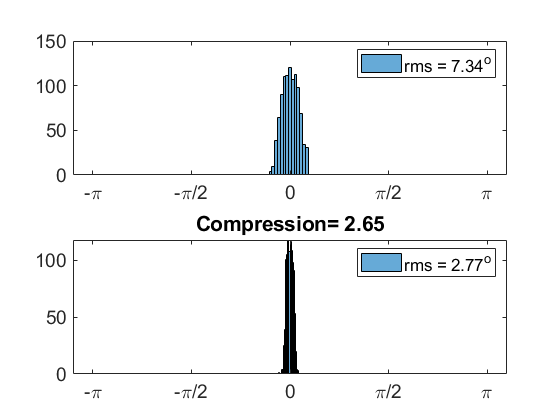

figure
compression=initial_rms/rot_rms;
subplot(2,1,1); histogram(x(:,1),'BinLimits',[-pi,pi])
legend(['rms = ',num2str(initial_rms,3),'^o'])
set(gca,'xtick',[-pi,-pi/2,0,pi/2,pi],'fontsize',14, ...
   'xticklabels',{'-\pi','-\pi/2','0','\pi/2','\pi'})
subplot(2,1,2); histogram(x1(:,1),'BinLimits',[-pi,pi])
legend(['rms = ',num2str(rot_rms,3),'^o'])
set(gca,'xtick',[-pi,-pi/2,0,pi/2,pi],'fontsize',14, ...
   'xticklabels',{'-\pi','-\pi/2','0','\pi/2','\pi'})
title(['Compression= ',num2str(compression,3)])

## Appendix 

The function` pendulumtracker()` receives the phase-space coordinates `x` at the start, the small-amplitude synchrotron frequency `omega`, and the integration time `dt` as input and returns the phase-space coordinates `xout`. Internally, it integrates the equations of motion for a mathematical pendulum in closed form using Jacobi elliptic functions. This is much faster than numerically integration, expecially for extremely large times, such as thousands or even millions of synchrotron periods. The coding closely follows Section 5.4, especially Equations 5.50 to 5.54. Here we use the elliptic functions from [https://github.com/moiseevigor/elliptic](https://github.com/moiseevigor/elliptic).

function xout=pendulumtracker(x,omega,dt)
k2=(0.5*x(2)/omega)^2+sin(0.5*x(1))^2; k=sqrt(k2);
if (x(1)>pi), x(1)=x(1)-2*pi; end
if (x(1)<-pi), x(1)=x(1)+2*pi; end
s=1; if (x(1)<0), s=-s; x(1)=-x(1); end
s1=1; if (x(2)<0), s1=-s1; end
if (k>1)   % outside separatrix
  kelf=ellipke(1/k2);
  trev=2*kelf/(k*omega);
  t0=mod(dt,trev);
  tmp=s1*k*omega*t0+s*elliptic12(0.5*x(1),1/k2);
  [sn,cn,dn]=ellipj(tmp,1/k2);  
  if (abs(tmp) > kelf), sn=-sn; end
  xout(1)=2*asin(sn);
  xout(2)=2*s1*omega*k*dn;
else       % inside separatrix
  trev=4*ellipke(k2)/omega;
  t0=mod(dt,trev);
  z0=asin(min(1,sin(0.5*x(1))/k));
  tmp=s1*omega*t0+s*elliptic12(z0,k2);
  [sn,cn,dn]=ellipj(tmp,k2);   
  xout(1)=2*asin(k*sn);
  xout(2)=2*s1*omega*k*cn;
end
end